# Atividade 07_01

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Detecção de bordas usando filtros de gradiente (Sobel na unha)

Vimos que o cálculo da magnitude do gradiente, M(i,j), é feito utilizando-se o operador módulo de um vetor (também chamado de norma). No entanto, para evitar o cálculo de uma raiz quadrada, economizando assim recursos computacionais, pode-se fazer uma simples soma dos valores absolutos (sem sinal) dos gradientes Gv e Gh. Teste esta afirmação comparando os resultados dos dois métodos.

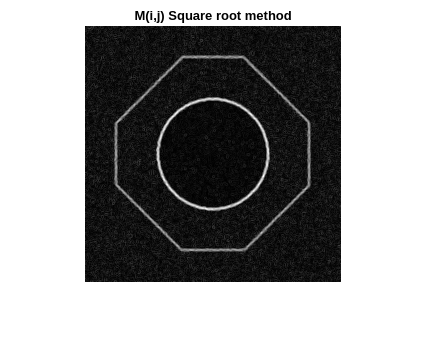

img = makeImSynthHex(256, 192, 64, 10);

doubleImg = im2double(img);

sobelH = fspecial("sobel");
sobelV = sobelH';

Gh = imfilter(doubleImg, sobelH, "replicate", "conv");
Gv = imfilter(doubleImg, sobelV, "replicate", "conv");


M1 = sqrt(Gv.^2 + Gh.^2);

figure, imshow(mat2gray(M1))
title("M(i,j) Square root method")

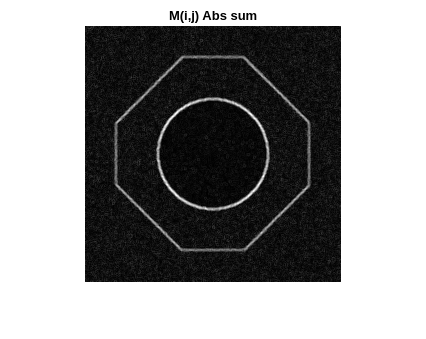


M2 = abs(Gv) + abs(Gh);

figure, imshow(mat2gray(M2))
title("M(i,j) Abs sum")

## Criar imagem de teste 

function s = makeImSynthHex(M, obj, bck, sd)
% Cria uma imagem sintética uint8 de dimensões
% M linhas e M colunas. O objeto tem nível de
% cinza obj e o fundo tem nível de cinza bck.
% O centro tem nível de cinza zero.
% Adiciona ruído Gaussiano de desvio padrão sd.
nrhs = floor(M/2);
nchs = floor(M/2);
a = triu(ones(nrhs,nchs))*bck;
b = tril(ones(nrhs,nchs),-1)*obj;
g1 = uint8(a+b);
g2 = fliplr(g1);
g3 = flipud(g2);
g4 = flipud(g1);
s = [g2 g1; g3 g4];
[r, c] = size(s);
g5 = ones(r,c);
g5(nrhs/4:end-(nrhs/4),nchs/4:end-(nchs/4)) = 0;
idx = g5 == 1;
s(idx) = bck;
circ = fspecial('gaussian', [r c], r/10);
circ = circ < max(circ(:))/10;
s = s .* uint8(circ);
% Suaviza, para o degrau não ser ideal
h = fspecial('average', [3 3]);
s = imfilter(s, h, 'replicate');
% Um ruidinho de média zero e desvio padrão sd
s = imnoise(s,'gaussian',...
(0/255),(sd/255)^2);
end